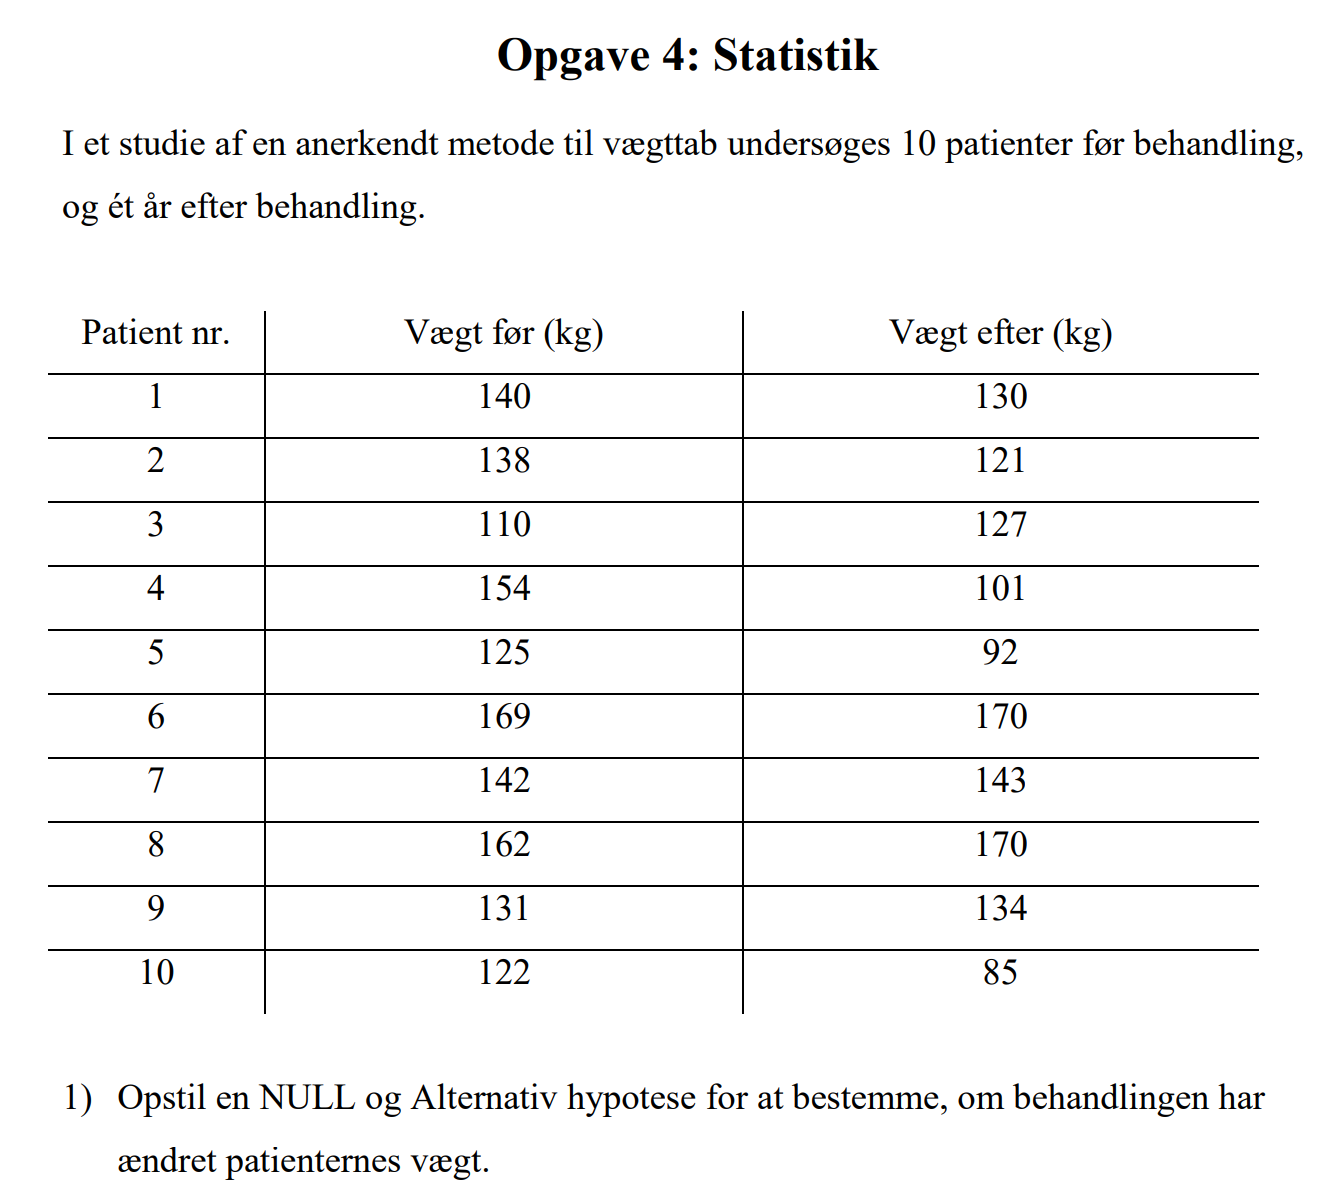

Null hypothesis. Brugt som testen af ingen forskel.


$$H_0 =\mu 1=\mu 2$$


Alternanive hypotese


$$H_1 =\mu 1\not= \mu 2$$


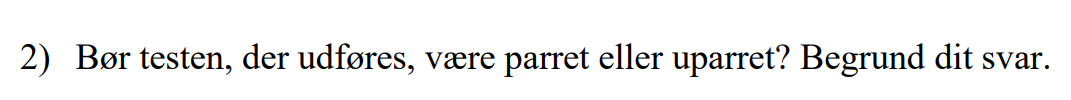

Da det er samme subjekt for før og efter, så bør det være en parret. 

patient = 1:1:10;
foer = [ 140 138 110 154 125 169 142 162 131 122];
efter = [130 121 127 101 92 170 143 170 134 85];

middelforskel = sum(efter-foer)/length(patient)

middelforskel = -12

s2 = 1/(length(patient)-1)*(sum((efter-foer-middelforskel).^2))

s2 = 508.8889

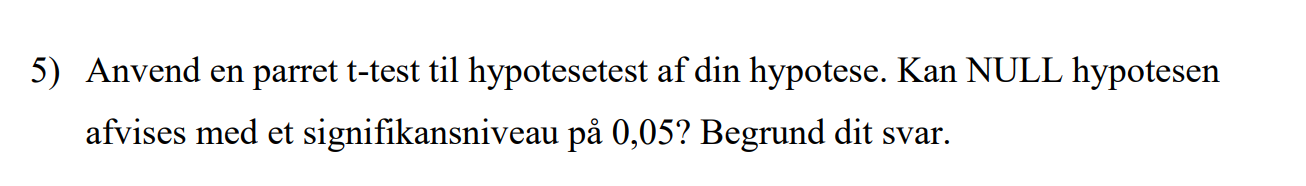

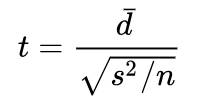

t = middelforskel/sqrt(s2/length(patient))

t = -1.6822

pval = 2*(1-tcdf(abs(t),(length(patient)-1)))

pval = 0.1268

Da pval er større end 0.05, så fejler vi med at afvise hypotese 0. 

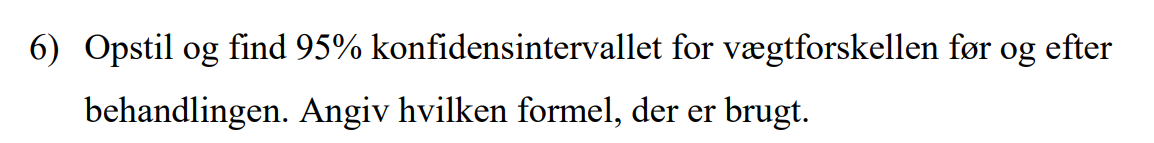

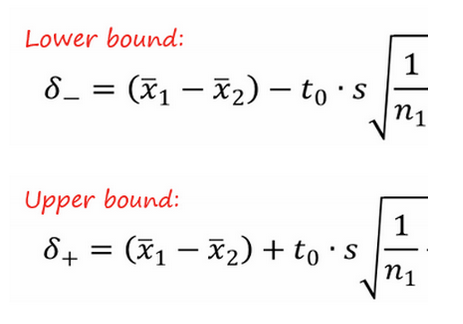

t0=tinv(0.975,(length(patient)-1))

t0 = 2.2622

koefMinus = middelforskel-t0*sqrt(s2)*sqrt((1/length(patient)))

koefMinus = -28.1374

koefPositiv = middelforskel + t0*sqrt(s2)*sqrt((1/length(patient)))

koefPositiv = 4.1374

## Resuldian og konfidensintervallet

antal = [28 46 44 63 104 148 172 187 223 236];
years = 1985:1:1994;
emperiskeMiddel = mean(antal)


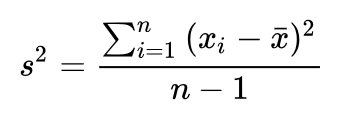

empiriskeVarianse2= sum((antal-emperiskeMiddel).^2)/(length(antal)-1)

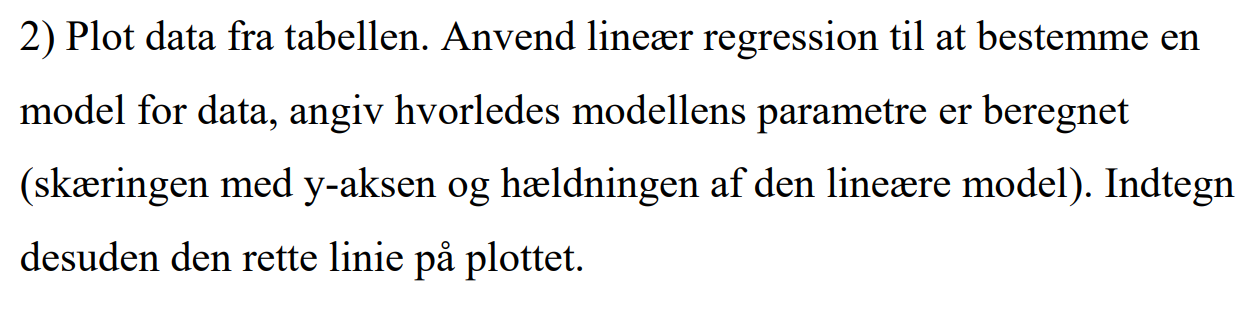

yearsMean = mean(years)

Benytter følgende formel for at finde skæringen og hældningen

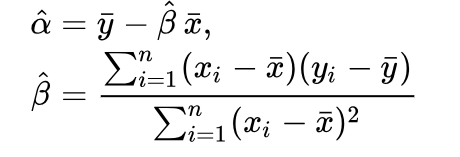

%Parameter estimat hældning
Beta = sum((antal - emperiskeMiddel) .* (years - yearsMean)) / sum((years - yearsMean).^2)

% Parameter estimat skæring
Alpha = emperiskeMiddel - Beta * yearsMean
linearModel = Alpha + years * Beta;
figure(2)
hold on
scatter(years, antal)
plot(years,linearModel)

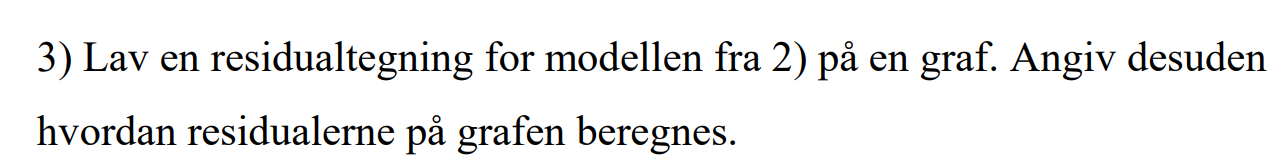

Residualtegning = antal - linearModel;
figure(3)
plot(years,Residualtegning,'b*')

Først findes standard deviationen 

n = length(antal)
sr2 = 1/(n-2)*sum((Residualtegning).^2)
t0 = tinv(0.975,(n-2))

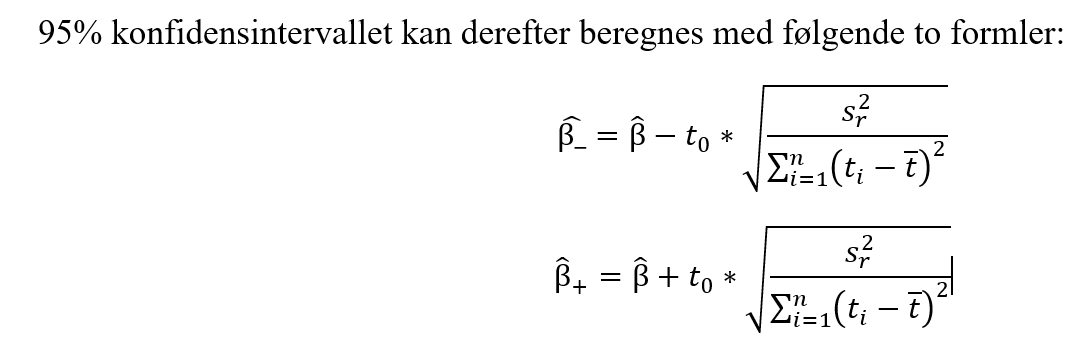

ConfMinus = Beta - t0 *sqrt(sr2/sum((years - yearsMean).^2))
ConfPositiv = Beta + t0 *sqrt(sr2/sum((years - yearsMean).^2))